# DeepInterpolation - Tiny Ophys Example

This example imports and uses a pre-trained DeepInterpolation model in MATLAB for inferring tiny ophys sample data.

## Find the deepinterpolation folder and add it to path

DI_path = uigetdir(pwd,'Select deepinterpolation folder')
addpath(genpath(DI_path))

## Import and Assemble Model

If not done so already, download the pretrained model from [here](matlab:open('./ReadMe.md')). Then import the trained model:

importednet = importKerasLayers('2019_09_11_23_32_unet_single_1024_mean_absolute_error_Ai93-0450.h5','ImportWeights',true);

Placeholders layers were added.  We'll replace the output with an [`maeRegressionLayer`](https://www.mathworks.com/help/deeplearning/ug/define-custom-regression-output-layer.html) from the documentation to make predictions.

placeholders = findPlaceholderLayers(importednet);
disp(placeholders)

  PlaceholderOutputLayer with properties:

    Name: 'conv2d_10_OutputLayer_PLACEHOLDER'

   Learnable Parameters
    No properties.

   State Parameters
    No properties.

  Show all properties



regressionnet = replaceLayer(importednet, placeholders.Name , maeRegressionLayer);
deepinterpnet = assembleNetwork(regressionnet)

deepinterpnet =   DAGNetwork with properties:

         Layers: [33×1 nnet.cnn.layer.Layer]
    Connections: [36×2 table]
     InputNames: {'input_1'}
    OutputNames: {'MAE Regression'}


## Analyze Network

Optionally analyze the network

if false
    analyzeNetwork(deepinterpnet)
end

## Import Sample TIFF Volume

ophys = tiffreadVolume('ophys_tiny_761605196.tif');

## Perform Inference

The network expects an input of size:

inputSize = regressionnet.Layers(1).InputSize

inputSize =    512   512    60


The size of the *ophys* image is:

size(ophys)

ans =    512   512   100


Make prediction with the equivalent sized input:

start_frame = ceil(39);
pre_frame = ceil(inputSize(3)/2);
try
    ophysinterp = predict(deepinterpnet, ophys(:,:,start_frame:(start_frame+inputSize(3)-1)));
catch
    warning('Problem using predict.  Returning null.');
    ophysinterp = [];
end

## Plot input movie

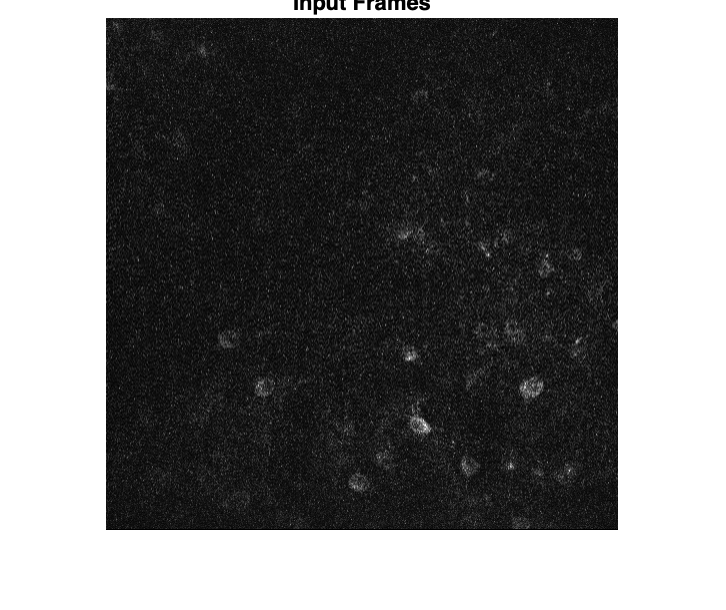

figure;
for idx = 1:inputSize(3)
    imshow(ophys(:,:,idx), [])
    pause(0.5)
end
title("Input Frames")

## Plot interpolation result

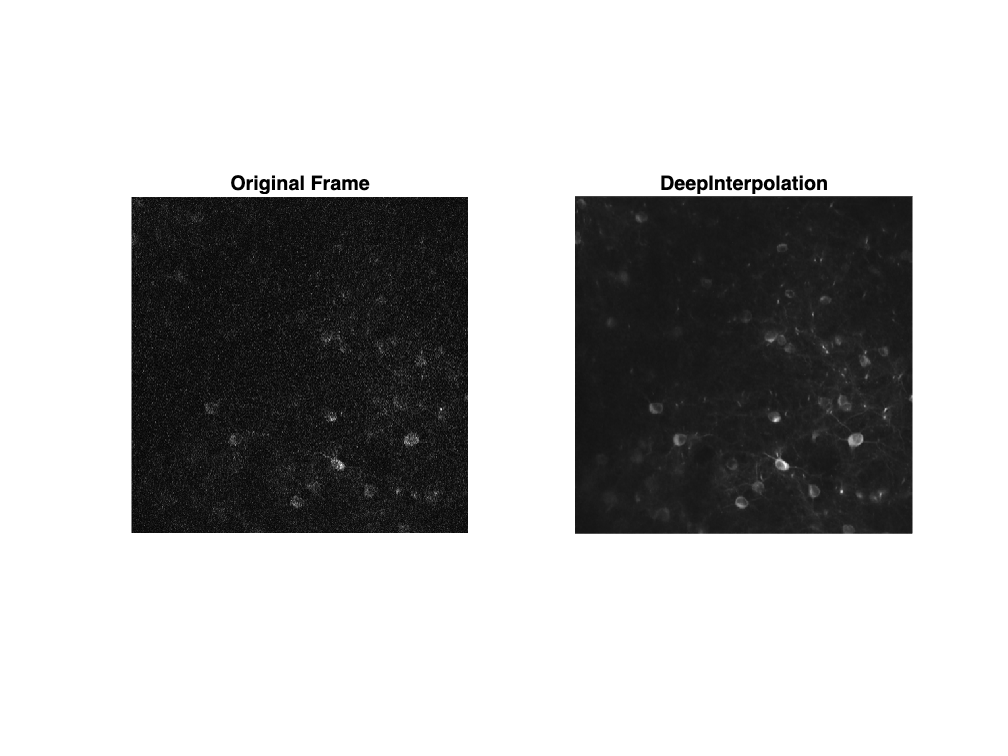

f = figure();
title("Deep Interpolation of tiny ophys data")
f.WindowState = 'maximized';
subplot(1,2,1)
imshow(ophys(:,:,start_frame+pre_frame),[])
title("Original Frame")
subplot(1,2,2)
imshow(ophysinterp, [])
title("DeepInterpolation")